# Synthetic Biology - Introduction to mathematical modelling applied to biology

# Code example 3: Mathematical Modelling with Matlab

2024 © Yadira Boada, Alejandro Vignoni

## Compartmental Models and the Zombies: The SZR Equations

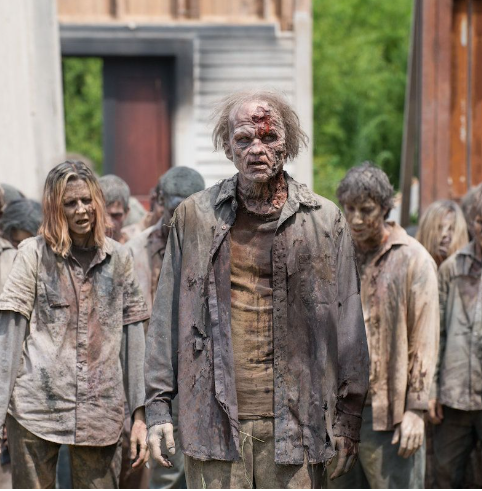

A zombie attack can also be modelled with a compartmental SZR model (SIR model).

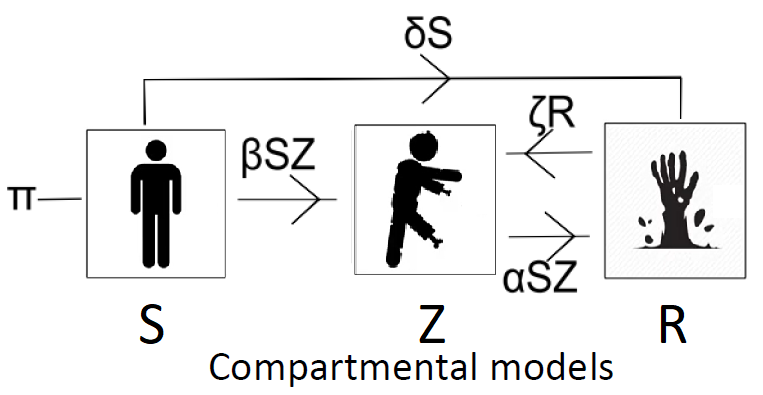

With the following equations


$$\dot{S} = \Pi -\beta S Z - \delta S \\
\dot{Z} = \beta S Z +\zeta R - \alpha S Z \\
\dot{R} = \delta S + \alpha S Z -\zeta R$$


Retrieved from the article:

Munz, Philip, et al. "When zombies attack!: mathematical modelling of an outbreak of zombie infection." Infectious Disease Modelling Research Progress 4 (2009): 133-150

The parameters are as follows:

Parameters:

Π: Human birth rate (constant)

𝛽 : Rate of humans infected by Zombies (converted)

𝛿: Death rate of humans (not related to zombie attack)

𝜁: Cadaver to zombie conversión rate

𝛼: Rate of Zombies murdered by Humans

**Main program**

First we must define the time vector: for this we discretise the time interval in order to find the numerical solutions of this equation for a particular initial condition that will be provided to us. We will discretise the interval [0,20], with a step of 0.2.

%Tiempo (days)
tfin=20; dt=0.2; 
tspan = 0:dt:tfin;

We define the parameters that in this case we are going to pass to the function. And we save them in the vector `params`. It is necessary to take into account the order in which we save the parameters in the vector `params`, it has to be the same order in which they are retrieved inside the function (at the end of the document).

% Parámetros:
p = 20;
b = 1.9;
d = 0.01;
z = 1;
a = 10;
params=[p,b,d,z,a];

and the initial conditions

% Condiciones iniciales
S0 = 20; %Condicion inicial de Susceptibles
Z0 = 0; %Cond. Inc. de Zombies
R0 = 0; %Cond. Inic. de Rem.
x0=[S0 Z0 R0];
% Tolerancias ode45
options=odeset('RelTol',1e-6,'Stats','off');

Finally, we solve the equation (simulate) with the ode command.

%Llamada solver ode45
[t,X] = ode23s(@(t,x) modelo_SZR(t,x,params),tspan,x0,options);


Then, we plot the solution.

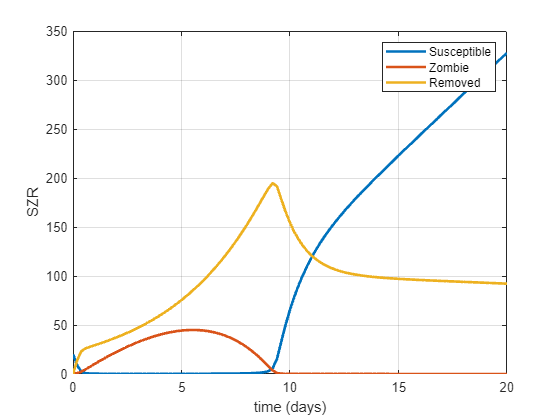

%Graficar respuesta modelo
figure;
plot(t,X,'LineWidth',2); grid on;
xlabel('time (days)'); ylabel('SZR');
legend('Susceptible','Zombie','Removed');

#### Definition of the ODE model/equation as a function

We now define a function that gives us the right-hand term of the differential equation. This expression will be evaluated at an instant $t$ and taking a value $x$, with the `parameters `given. As you can see, you need to pass to the function the following: 

* the value of $t$ where the function is evaluated,

* the value of $x$ where the function is evaluated,

* the parameters that allow us to define the equation.

**ODE Models**

function [dx_dt]= modelo_SZR(t,x,params)
% Model parameters:
%params=[p,b,d,z,a];
p= params(1,1);
b= params(1,2);
d= params(1,3);
z= params(4);
a= params(5);
% Define the variables
S = x(1);
Z = x(2);
R = x(3);
%Define the equations
dS =  p               - b .* S .* Z           - d .* S;

dZ =  b .* S  .* Z    + z .* R                - a .* S .* Z;

dR =  d .* S          - z .* R                + a .* S .* Z;
%Collect the derivatives in one vector
dx_dt = [dZ; dS; dR];

end